# Hands-on project 1:  Non-NN Machine Learning

## Preparation of workspace and constants

First of all the workspace is cleaned in order to have a common starting point.

% Clean workspace
clear;

Then some NECESSARY parameters are added to the workflow:

-  DATASET_PATH: relative path of the used dataset

- K_FOLD_PARTITIONS: number of subdivision of the training set during cross validation of the models

- PERCENTAGE_DATA_TRAINING: percentage of data used to train the model (from 0% to 100%). Suggested values are between 75% and 80%.

- NUMBER_OPTIMIZATION: Number of iteration in Bayesian optimization of the models

% Constants used
DATASET_PATH ="data/seeds_dataset.csv";
K_FOLD_PARTITIONS = 6;
PERCENTAGE_DATA_TRAINING = 80; % From 0 to 100
NUMBER_OPTIMIZATION = 100;

## Reading data from dataset and shuffling

In order to obtain a randomized order of the data (in the original dataset we had all the data sorted by class) we use the function randperm.

After that we divide the total dataset in training set and test set.

A test set is used to ensure that the model does not overfit to the training data. This is because the model has no idea how to predict the output to this data, and if these guesses are too far from the correct answers, that means the model is overfit or wrong.

% Import dataset from file
dataset = readtable(DATASET_PATH);

% Shuffle data to obtain a random order
shuffled = dataset(randperm(size(dataset, 1)), :);

% Division on dataset
division_row_data = (PERCENTAGE_DATA_TRAINING/100) * size(shuffled,1);
trainSet = shuffled(1 : division_row_data,:);
testSet = shuffled(division_row_data + 1 : size (shuffled, 1),:);

The division in labels and data is made in order to have a more human friendly function generation (code easier to be read).

% Division of data and labels
trainLabels = trainSet(:, 8);
trainSet(:,8) = [];
testLabels = testSet(:, 8);
testSet(:,8) = [];

% Cleaning of data
clear percentage_data_train division_row_data shuffled;

## Model creation and cross validation

### Model creation

The "Classification Learners" application was used to identify the best models for classifying wheat. Since Neural Networks weren't allowed in this task, the most promising models found were Linear SVM and Cubic KNN.

### SVM

Most primising parameters for SVM, after an hyperparameters optimization, were a linear function and standardized data. Here explained what this means:

-     Linear: the prediction is based on a dividion of the data given by a linear function

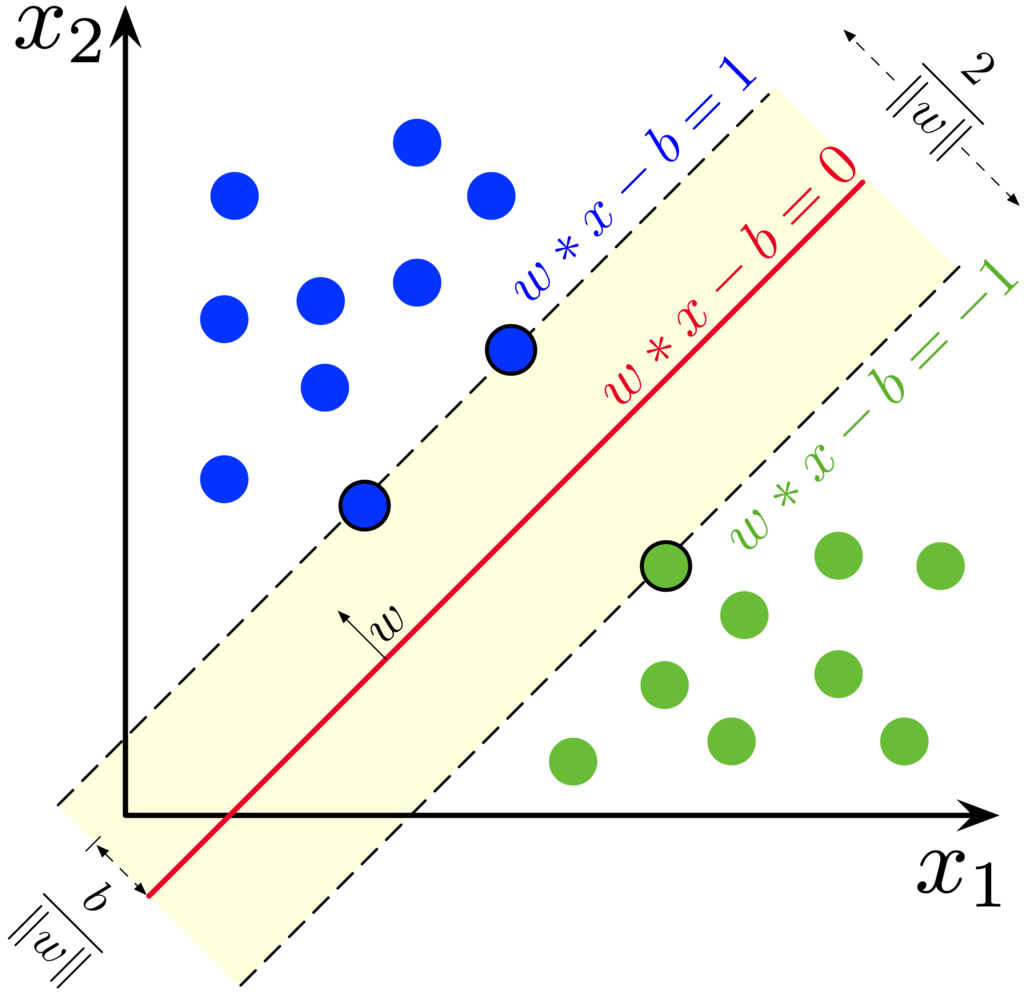

- Standardize: according to Matlab help guide, this option centers and scales each predictor variable by the corresponding weighted column mean and standard deviation

template = templateSVM(...
    'KernelFunction', 'linear', ...
    'Standardize', true);

After the definition of the SVM, the model is fitted using the function "fitecoc" that allows us to create a non-binary classifier. To create the mode train dataset and labels are used.

 SVM = fitcecoc(...
    trainSet, ...
    trainLabels, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', {'canadian'; 'kama'; 'rosa'});

### KNN

As said before, for KNN model the best parameters were cubic distance with 10 neighbors. 

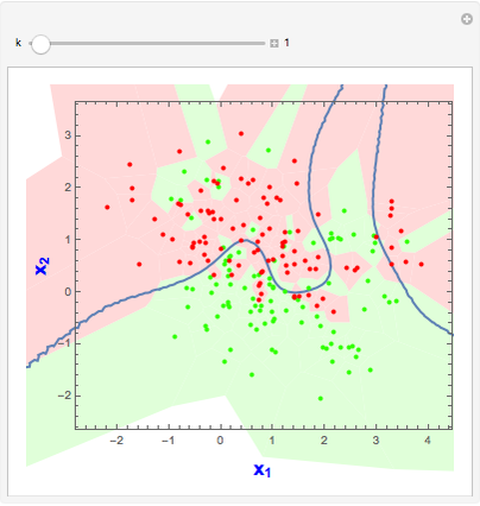

Parameters used are:

- Distance: function that is used to calculate the distance between the data and the neighbors

- Exponent: exponent of the polynomial function

- DistanceWeight: Way the different neighbors are weighted

- Standardize: according to Matlab help guide, this option centers and scales each predictor variable by the corresponding weighted column mean and standard deviation

 % KNN
 KNN = fitcknn(trainSet, trainLabels,'Distance', 'Minkowski', ...
        'Exponent', 3, ...
        'NumNeighbors', 10, ...
        'DistanceWeight', 'Equal', ...
        'Standardize', true);

### Cross validation

After the setup of the models a Cross Validation of the data is performed.

Cross validation of data is useful because it helps to have an augmentation of the dataset that we use to train the models. This is because the entire training set is divided into N subsets and then the model is trained on N-1 sets and tested on the other. In this way, a set of models is obtained and the best one is selected.

The picture above shows the process.

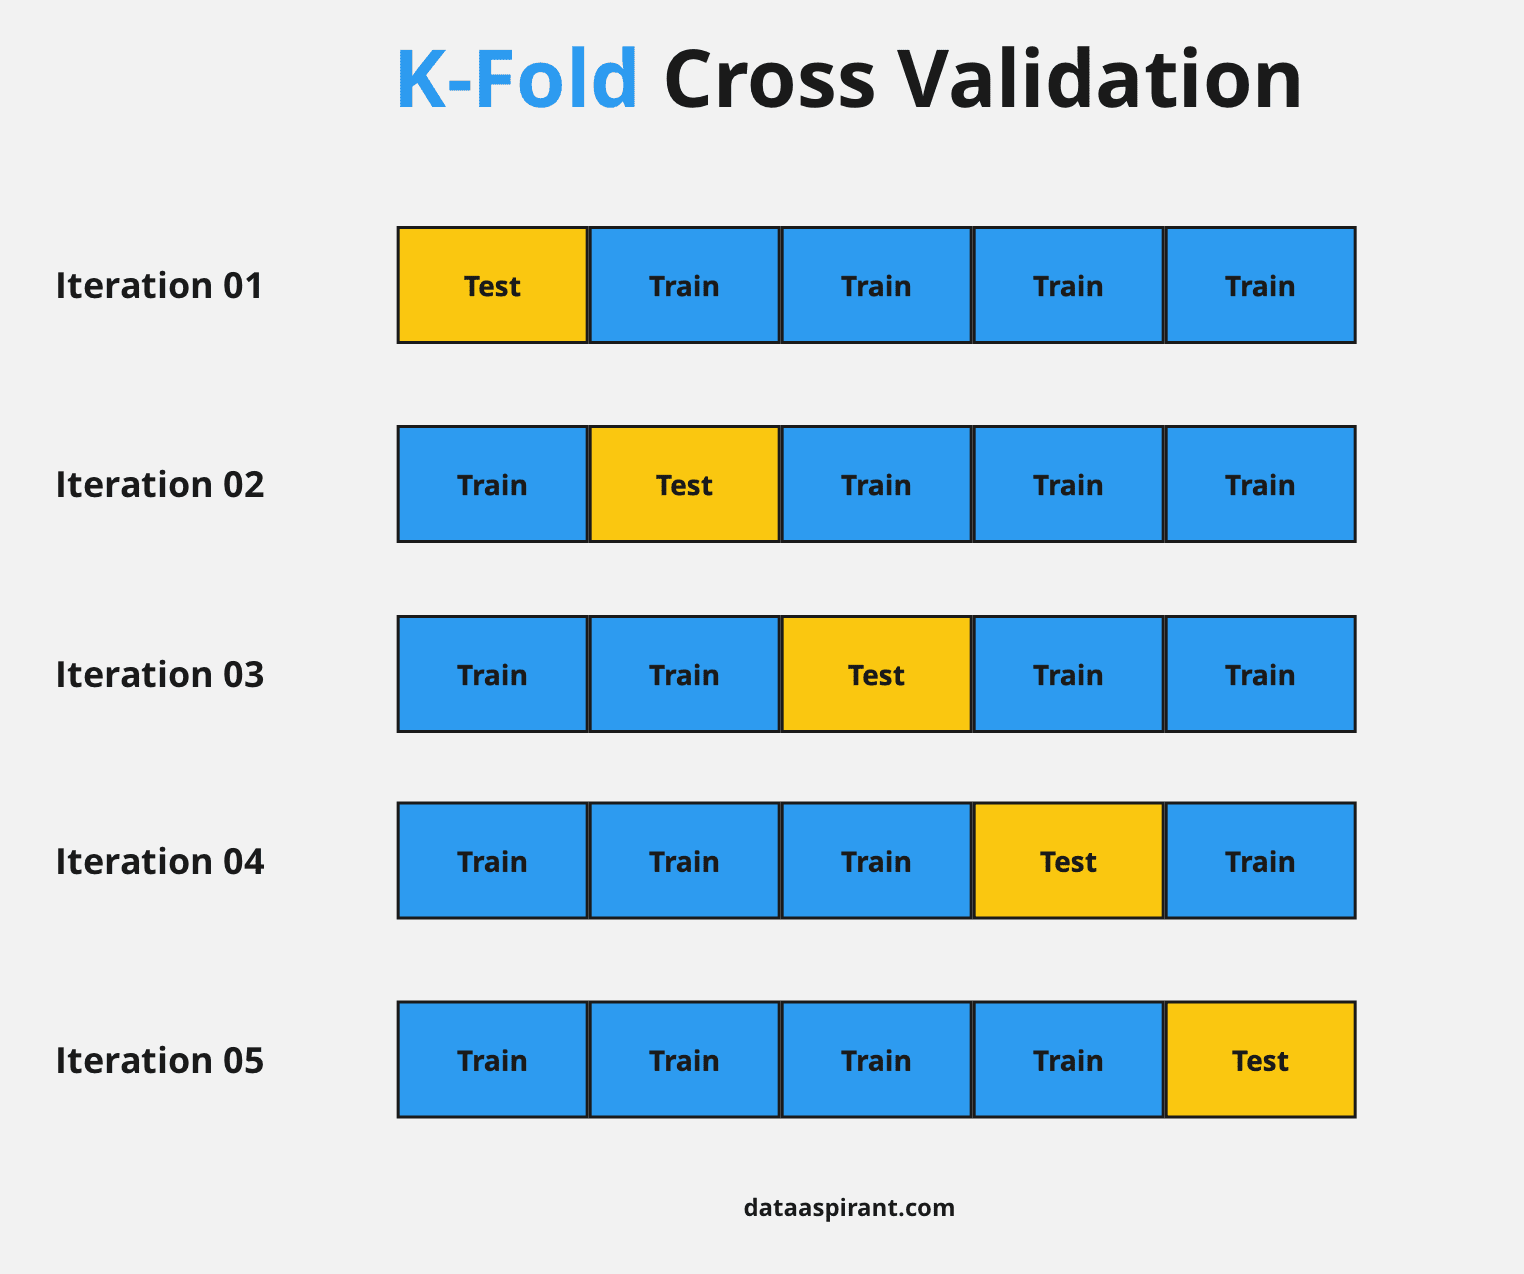

If the dataset has problems or the model is not balanced, then cross validation helps us to find these problems.

% Perform cross-validation
CVModel_SVM = crossval(SVM, 'KFold', K_FOLD_PARTITIONS);
CVModel_KNN = crossval(KNN, 'KFold', K_FOLD_PARTITIONS);

% Calculation of validation accuracy
validationAccuracySVM = 1 - kfoldLoss(CVModel_SVM, 'LossFun', 'ClassifError');
validationAccuracyKNN = 1 - kfoldLoss(CVModel_KNN, 'LossFun', 'ClassifError');
% SVM accuracy
accuracy = kfoldLoss(CVModel_SVM, 'Mode', 'individual');

Here the accuracy values obtained from SVM and KNN cross validation:

disp("Accuracy of cross validation folders in SVM: ");

Accuracy of cross validation folders in SVM: 


for i = 1 : size(accuracy)
    disp(100 - accuracy(i)*100 + "%");
end

96.4286%
92.8571%
78.5714%
96.4286%
96.4286%
92.8571%


disp("Mean accuracy in validation for SVM: " + validationAccuracySVM*100 + "%");

Mean accuracy in validation for SVM: 92.2619%


% KNN accuracy
accuracy = kfoldLoss(CVModel_KNN, 'Mode', 'individual');
disp("Accuracy of cross validation folders in KNN: ");

Accuracy of cross validation folders in KNN: 


for i = 1 : size(accuracy)
    disp(100 - accuracy(i)*100 + "%");
end

96.4286%
96.4286%
85.7143%
92.8571%
82.1429%
82.1429%


disp("Mean accuracy in validation for KNN: " + validationAccuracyKNN*100 + "%");

Mean accuracy in validation for KNN: 89.2857%


% Cleaning of data
clear CVModel_SVM CVModel_KNN validationAccuracySVM validationAccuracyKNN accuracy;

## Optimized models and Comparison

### Optimization

The use of templates in this process is crucial to obtain an automatic standardization of the data. After that, a Bayesian optimization is performed to optimize some parameters of the model, as well as Cross-validation to improve stability.

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | der          |
|===================================================================================================================================|
|    1 | Best   |    0.059524 |     0.34319 |    0.059524 |    0.059524 |       439.65 |            - |       linear |            - |
|    2 | Accept |    0.083333 |     0.20916 |    0.059524 |    0.066627 |      0.52856 |            - |   polynomial |            2 |
|    3 | Accept |     0.10714 |      0.1826 |    0.059524 |    0.061214 |       2.1695 |            - |   polynomial |            4 |
|    4 | Accept |     0.65476 |      0.1806 |    0.059524 |   

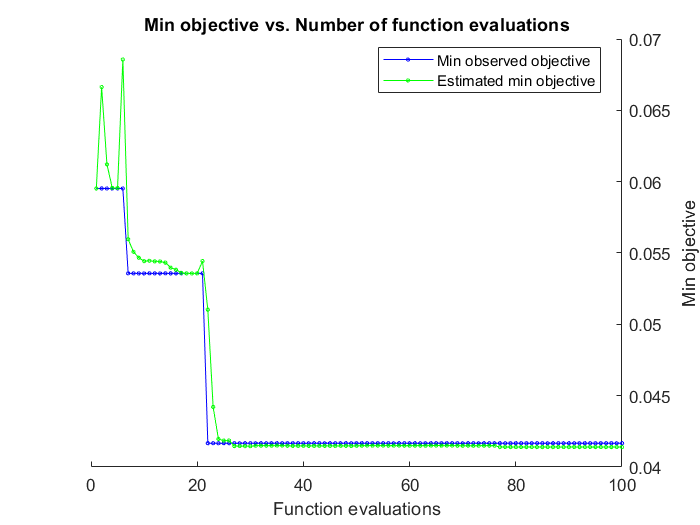


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 62.9416 seconds
Total objective function evaluation time: 18.6882

Best observed feasible point:
    BoxConstraint    KernelScale    KernelFunction    PolynomialOrder
    _____________    ___________    ______________    _______________

       64.157            NaN            linear              NaN      

Observed objective function value = 0.041667
Estimated objective function value = 0.042143
Function evaluation time = 0.23109

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale    KernelFunction    PolynomialOrder
    _____________    ___________

% SVM optimized model
opt_template = templateSVM("Standardize", true);
Opt_SVM = fitcecoc(trainSet, trainLabels, ...
    'OptimizeHyperparameters', {'BoxConstraint','KernelScale','KernelFunction','PolynomialOrder'} ,...
    'HyperparameterOptimizationOptions', struct('CVPartition',cvpartition(table2cell(trainLabels),'KFold',K_FOLD_PARTITIONS), ...
    'AcquisitionFunctionName','expected-improvement-plus', ...
    'MaxObjectiveEvaluations', NUMBER_OPTIMIZATION), "Learners", opt_template);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |
|====================================================================================================================|
|    1 | Best   |    0.095238 |     0.19185 |    0.095238 |    0.095238 |           53 |    cityblock | squaredinver |
|    2 | Accept |     0.11905 |     0.17883 |    0.095238 |    0.096185 |            2 |  mahalanobis | squaredinver |
|    3 | Best   |    0.089286 |      0.1863 |    0.089286 |    0.090011 |            8 |    euclidean |        equal |
|    4 | Accept |    0.095238 |     0.16384 |    0.089286 |    0.089287 |            2 |    cityblock | squaredinver |
|    5 | Accept |     0.11905 |     0.16954 |   

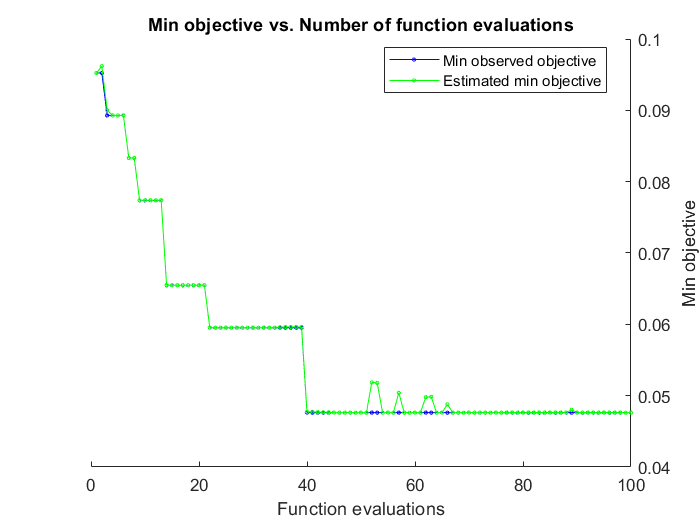


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 49.8488 seconds
Total objective function evaluation time: 17.61

Best observed feasible point:
    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________

         1          chebychev    squaredinverse

Observed objective function value = 0.047619
Estimated objective function value = 0.047636
Function evaluation time = 0.15924

Best estimated feasible point (according to models):
    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________

         1          chebychev       inverse    

Estimated objective function value = 0.047616
Estimat

% KNN optimized model
opt_template = templateKNN("Standardize", true);
Opt_KNN = fitcecoc(trainSet, trainLabels,'OptimizeHyperparameters',{'NumNeighbors','Distance','DistanceWeight'},...
    'HyperparameterOptimizationOptions', struct('CVPartition',cvpartition(table2cell(trainLabels),'Kfold',K_FOLD_PARTITIONS), ...
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'MaxObjectiveEvaluations', NUMBER_OPTIMIZATION),"Learners", opt_template);

## Test

A real prediction based on non-optimized and optimized models can now be executed.

The predictions (SVM_prediction and KNN_prediction) from testSet will be compared with the correct testLabel saved at the beginning.

One way to show how good is the prediction is to use a Confusion chart.

### SVM confusion chart

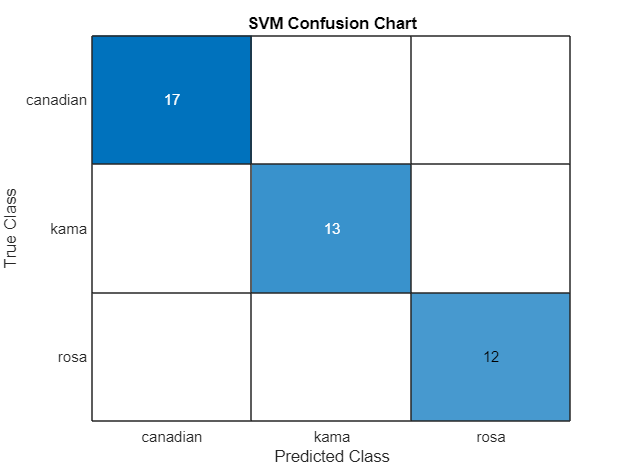

% Test SVM
SVM_prediction = SVM.predict(testSet);
svm_confusion_chart = confusionchart(table2array(testLabels), SVM_prediction, Title="SVM Confusion Chart");     % plot confusion chart

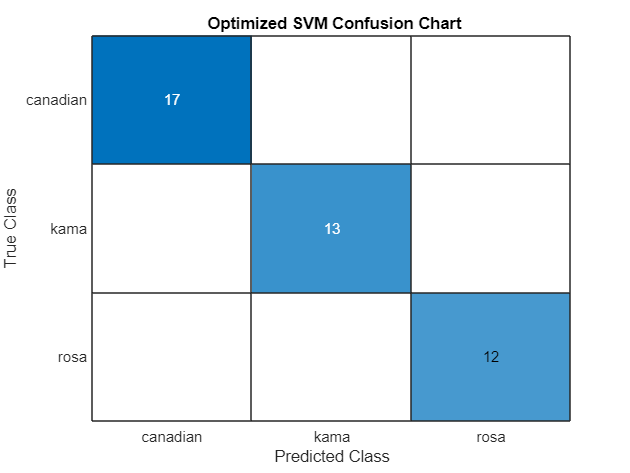

% Test Optimized SVM
Optimized_SVM_prediction = Opt_SVM.predict(testSet);
opt_svm_confusion_chart = confusionchart(table2array(testLabels), Optimized_SVM_prediction, Title=" Optimized SVM Confusion Chart");     % plot confusion chart

% Calculation accuracy SVM
    errors = strcmp(SVM_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for SVM: " + accuracy + "%");

Accuracy in test for SVM: 100%


% Cleaning of data
clear errors accuracy;

% Calculation accuracy Optimized SVM
    errors = strcmp(Optimized_SVM_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for optimized SVM: " + accuracy + "%");

Accuracy in test for optimized SVM: 100%


% Cleaning of data
clear errors accuracy;

### KNN confusion chart

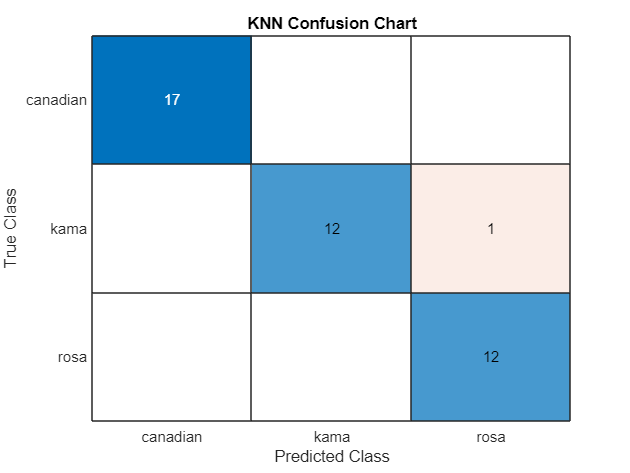

% Test KNN
KNN_prediction = KNN.predict(testSet);
knn_confusion_chart = confusionchart(table2array(testLabels), KNN_prediction, Title="KNN Confusion Chart");     %plot confusion chart

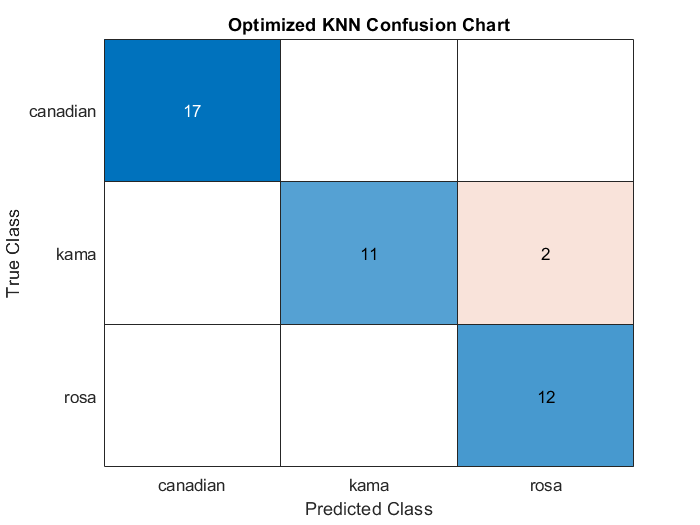

% Test Optimized KNN
Optimized_KNN_prediction = Opt_KNN.predict(testSet);
opt_knn_confusion_chart = confusionchart(table2array(testLabels), Optimized_KNN_prediction, Title="Optimized KNN Confusion Chart");     %plot confusion chart

% Calculation accuracy KNN
    errors = strcmp(KNN_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for KNN: " + accuracy + "%");

Accuracy in test for KNN: 97.619%


% Cleaning of data
clear errors accuracy;

% Calculation accuracy Optimized KNN
    errors = strcmp(Optimized_KNN_prediction, table2array(testLabels));
    accuracy = sum(errors)*(100/numel(errors));
disp("Accuracy in test for optimized KNN: " + accuracy + "%");

Accuracy in test for optimized KNN: 95.2381%


% Cleaning of data
clear errors accuracy PERCENTAGE_DATA_TRAINING DATASET_PATH K_FOLD_PARTITIONS;

### DISCLAIMER

Since the first models were implemented via the "Classification Learner" application, their parameters were already optimized. This is why sometimes the proposed non-optimized models perform as well as, or even slightly better, than the optimized ones.